# Signal Analysis for Protocol 2

Water level - 23.4cm

Bottom of Tub - 37cm

Peak Response- 45cm

From the plot with the depths of the amplitudes. The curves oscillate harmonically with increasing amplitude. Higher radar response the deeper the chicken is in the water. Possibility of estimating depth with just the period of the oscillaton.

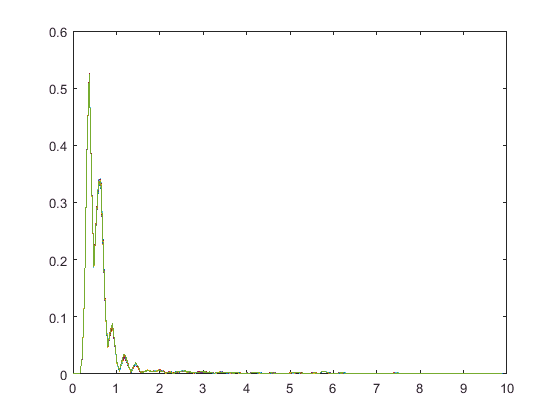

clc
clear variables
close all

% Settings
folder = 'chicken';
dataType = 'bb';
dacMIN = 0;
dacMAX = 1400;
freq = 3;
global variableName;
variableName = strcat(dataType, num2str(dacMIN), '_', num2str(dacMAX), 'f', num2str(freq));
x = linspace(0.0, 9.9, 186);

% Analsis
load('chicken_water/sinusoid_D-1cm_T6_A10_1.mat', variableName);

for i=1:250
   plot(x, abs(bb0_1400f3(i,:)));
   hold on;
end
hold off;

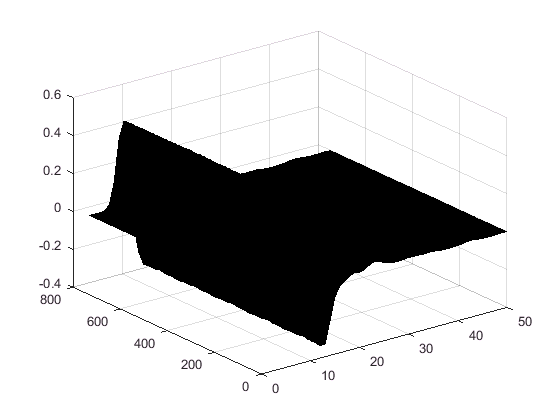

surf(real(bb0_1400f3(1:750, 1:50)));

## Average out the radar data

objdataavg = zeros(length(objdata), length(objdata(1, 1).(variableName)));

Undefined function or variable 'objdata'.

baselineavg = abs(mean([baseline(1).(variableName); baseline(2).(variableName); baseline(3).(variableName)]));
t = 1;
for i = depths
    objdata1 = abs(objdata(t, 1).(variableName));
    objdata2 = abs(objdata(t, 2).(variableName));
    objdata3 = abs(objdata(t, 3).(variableName));
    objdataavg(t,:) = mean([objdata1; objdata2; objdata3]) - baselineavg;
    t = t + 1;
end

for i = 11:-1:6
   plot(x, objdataavg(i,:)); 
   hold on;
end
xlim([0, 1]);
legend('show');
title('Going from 0mm to -8mm - Baseband');
hold off;

## Mean of the Data

objdataavgmean = objdataavg;
for i = 1:length(depths)
   objdataavgmean(:,i) = objdataavgmean(:,i) .* depths(i);
end
objdataavgmean = mean(objdataavgmean');
total = mean(objdataavg');
bar(depths, objdataavgmean ./ total);
title('Mean Depth')
xlabel('Depth of Chicken')
ylabel('Average Depth of Signal')

## Changes in the the amplitude over time

surf(x(1:20), depths, objdataavg(1:end, 1:20));
xlabel('Distance From Radar');
ylabel('Depth of Chicken Immersed');
zlabel('Amplitude of Radar');
title('Relationship between Depth of Chicken and distance from Radar');